## Problem 5

**a)**

clc;
clear;
close all;

% Define Constants
ao = 5.292e-11;
a = 3 * ao; 
gamma1 = -2;


kx = linspace(-4*pi/a, 4*pi/a, 150); % Extending beyond first BZ
ky = linspace(-4*pi/a, 4*pi/a, 150);
[KX, KY] = meshgrid(kx, ky);

E_plus = gamma1 * sqrt(1 + 4*cos(sqrt(3)*ao*KY/2) .* cos(ao*KX/2) + 4*cos(ao*KX/2).^2);
E_minus = -gamma1 * sqrt(1 + 4*cos(sqrt(3)*ao*KY/2) .* cos(ao*KX/2) + 4*cos(ao*KX/2).^2);

figure;
hold on;
grid on;

% Upper and Lower Bands
surf(KX, KY, E_plus, 'EdgeColor', 'none'); % Upper π* band
surf(KX, KY, E_minus, 'EdgeColor', 'none'); % Lower π band

xlabel('k_x (Reciprocal Space)', 'FontSize', 12);
ylabel('k_y (Reciprocal Space)', 'FontSize', 12);
zlabel('Energy E(k) [eV]', 'FontSize', 12);
title('Band Structure of Graphene Beyond First BZ', 'FontSize', 14);
colormap jet;
colorbar;
view(3);
set(gca, 'FontSize', 12);

**b)**

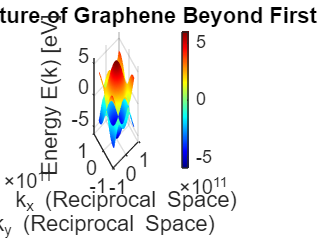

K = [2*pi/(3*ao), 2*pi/(sqrt(3)*ao)];
Gamma = [0, 0];
M = [0.5, 0];

k_KG = [linspace(K(1), Gamma(1), 100)', linspace(K(2), Gamma(2), 100)'];
k_GM = [linspace(Gamma(1), M(1), 100)', linspace(Gamma(2), M(2), 100)'];
k_MK = [linspace(M(1), K(1), 100)', linspace(M(2), K(2), 100)'];

E_KG = gamma1 * sqrt(1 + 4*cos(sqrt(3)*ao*k_KG(:,2)/2) .* cos(ao*k_KG(:,1)/2) + 4*cos(ao*k_KG(:,1)/2).^2);
E_GM = gamma1 * sqrt(1 + 4*cos(sqrt(3)*ao*k_GM(:,2)/2) .* cos(ao*k_GM(:,1)/2) + 4*cos(ao*k_GM(:,1)/2).^2);
E_MK = gamma1 * sqrt(1 + 4*cos(sqrt(3)*ao*k_MK(:,2)/2) .* cos(ao*k_MK(:,1)/2) + 4*cos(ao*k_MK(:,1)/2).^2);

E = [E_KG; E_GM; E_MK];
E = E(:);
plot(E);

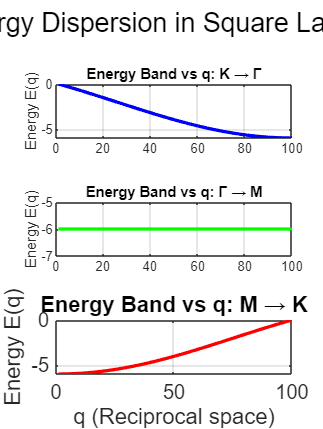


figure;

% M -> Gamma
subplot(3,1,1);
plot(E_KG, 'b', 'LineWidth', 2);
title('Energy Band vs q: K → Γ');
ylabel('Energy E(q)');
grid on;

% Gamma -> X
subplot(3,1,2);
plot(E_GM, 'g', 'LineWidth', 2);
title('Energy Band vs q: Γ → M');
ylabel('Energy E(q)');
grid on;

% X -> M
subplot(3,1,3);
plot(E_MK, 'r', 'LineWidth', 2);
title('Energy Band vs q: M → K');
xlabel("q (Reciprocal space)");
ylabel('Energy E(q)');
grid on;

% Adjust layout for better readability
sgtitle('Energy Dispersion in Square Lattice', 'FontSize', 16);
set(gca, 'FontSize', 12);
set(gcf, 'Position', [100, 100, 600, 800]);